# Documentation of Daisyworld with greenhouse effects.

## Introduction

Daisyworld is a simplified model that describes the feedback mechanism between the life and environment of a planet. Daisyworld is a planet populated by two types of flowers: black daisies and white daisies (see Figure 1). The colour of the daisies modifies the albedo of the planet and, therefore, its temperature. In return, the growth rate of the daisies is affected by the change of planetary temperature. The change in global temperature is also affected by the greenhouse effect, which can trigger a perturbation of the feedback mechanism. THe present example shows how different parameters can affect the growth of the black and white daisies populating Daisyworld.Note that the greenhouse effect is not included in the original Daisyworld model, but it is relevant here to mimic a climate change event. The main source of inspirations for this example are the study by [1] and the review paper by [2]

                                                                                             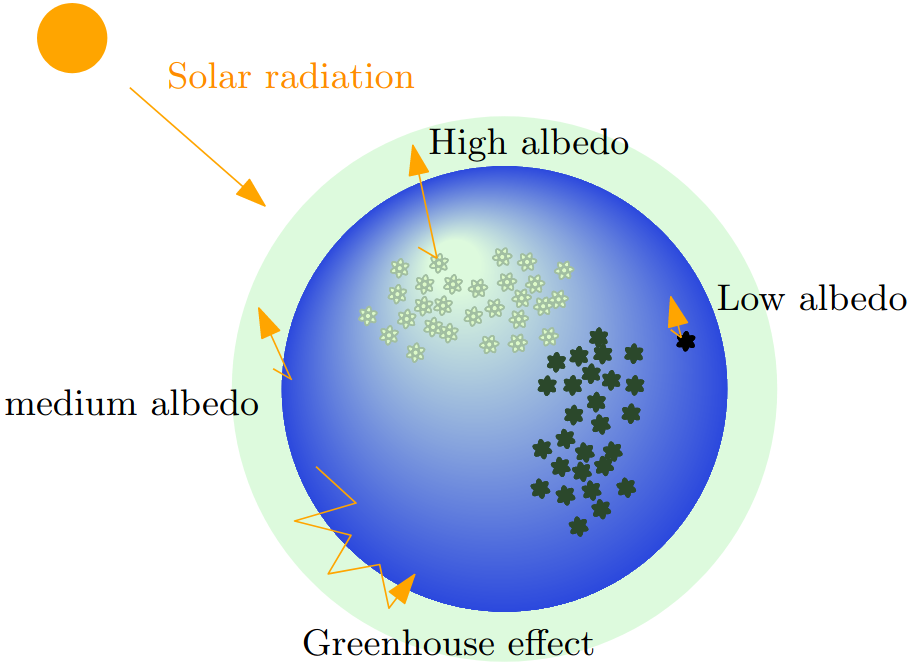

**                                                                      Figure 1: Sketch of Daisyworld with Greenhouse effect included into the model.**

The present model is based on four coupled ordinary differential equations:


$$\frac{\mathrm{d}{\alpha}_w}{\mathrm{d} t}  =	\alpha_w  \left[ \alpha_g  \beta(T_w) -\gamma \right] \\
		\frac{\mathrm{d}{\alpha}_b}{\mathrm{d} t}  =	\alpha_b  \left[ \alpha_g  \beta(T_b) -\gamma \right] \\ 
		\frac{\mathrm{d}{T}}{\mathrm{d} t}  = \frac{S \times L  \left(1-A\right) - \sigma T^4 \left(1-E\right)}{c} \\
		\frac{\mathrm{d}{E}}{\mathrm{d} t}  = a - b \times E  \left( \alpha_w +\alpha_b \right)$$


where $\alpha_w$ and $\alpha_b
$ is the fractional area coverage of white daisies and black daisies on the surface of the planet with values between 0 and 1; $T$ is the planetary or global temperature in Kelvin (K); $E$ is the greenhouse effect with value between 0 and 1;  $S$ is the average solar irradiance at the planet surface and is expressed in \si{\watt\per\meter\squared}; $L$ is a coefficient for the luminance of the sun with a value $L = 1
$ per default; *A *is the total albedo of the planet with values between 0 and 1;$\;\sigma =5\ldotp 67\times {10}^{8\;} \mathrm{W}\;{\mathrm{m}}^{-2} \;{\mathrm{K}}^{-4}$ is the Stefan-Boltzmann constant; $\gamma
$ is the death rate of the flowers; $a$ the emission rate of greenhouse gas by an undefined source whereas $b$ is the rate absorption of greenhouse gas by the daisies. Finally, $c $ is the thermal inertia (or average heat capacity) of the planet in ${\mathrm{K}}^{-1}$.

	The function $\beta(T_i)$ with $i = \left\lbrace w,b \right\rbrace$ represents the growth rate (or 'birth' rate) of the daisies. It depends on the local temperature of the flower $T_i$ and an optimal growth temperature $T_{\mathrm{opt}} = 292.5$ K. It is here expressed as a Gaussian function:


$$\beta (T_i)  = \exp \left[-\frac{\left(T_i-T_{\mathrm{opt}}\right)^2}{70}\right]$$


The function $\beta (T_i)$ has values between 0 (no grow) and 1 (optimal grow) as shown in Fig 2

                                                        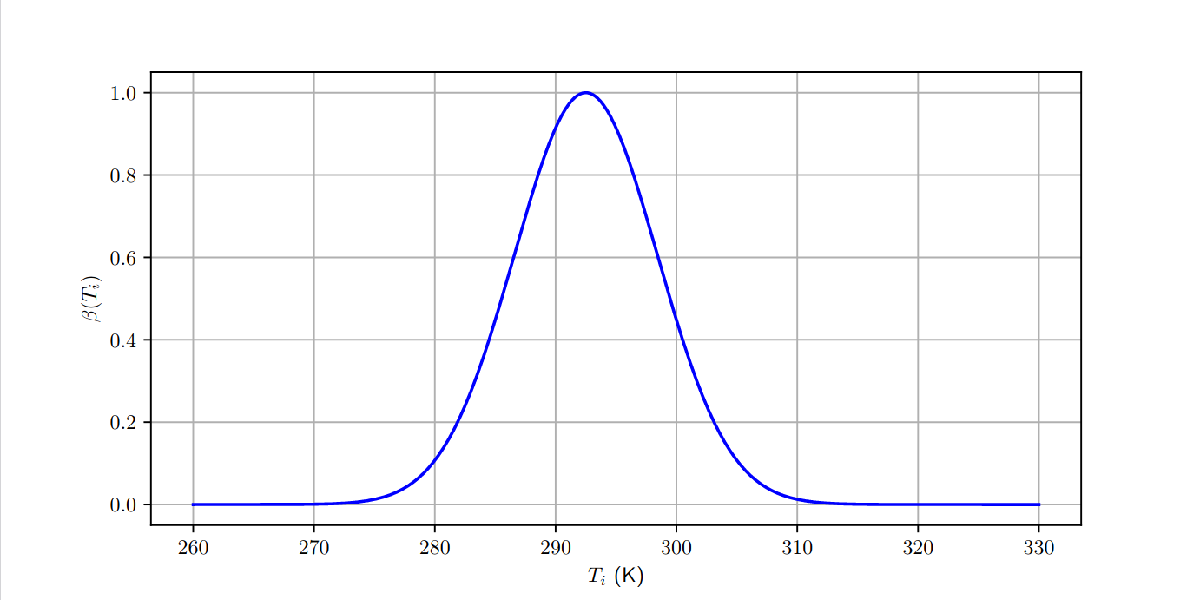

                                                            **Figure 2: Daisy growth rate **$\beta (T_i) $**as a function of the local temperature **$T_i$**, **$i = \left\lbrace w,b \right\rbrace$** .**

	The fractional area $ \alpha_g$ not covered by flowers is the ground (no ocean, sea or lake are modelled here), such that

	
$$\alpha_g  = 1 - \alpha_w -\alpha_b$$


	Which leads to the planetary albedo of Daisyworld *A*, defined as

	 
$$A  = \alpha_w \times a_w + \alpha_b \times a_b + \alpha_g \times a_g$$


	where $a_w$, $ a_b $ and $ a_g$ are the albedo of the white daisies, black daisies and the ground, respectively. In the present case, $ 0 < a_b < a_g < a_w <1$.

**References**

[1] Susana LD Paiva, Marcelo A Savi, Flavio M Viola, and Albino JK Leiroz. Global warming description using daisyworld model with greenhouse gases. Biosystems, 125:1–15, 2014.

[2] Andrew J Wood, Graeme J Ackland, James G Dyke, Hywel TP Williams, and Timothy M Lenton. Daisyworld: a review. Reviews of Geophysics, 46(1), 2008.

## Parameter definition

clearvars;close all;clc;
dt = 1 ; % time step is one day (if dt = 1/24 , the time stpe is 1 h)
fs = 1/dt ; % sampling frequency
Ndays = 10*365 ; % ca. 10 years of data
N = Ndays*fs ; % number of discrete time steps for the simulation
t = [0:N-1].*dt; % time vector
L = 1*ones(1,N) ; % Luminosity (L = 1 for same luminosity as for the sun)
alphaW0 = 0.01; % initial percentage of white daisies at the surface of the planet
alphaB0 = 0.01 ; % initial percentage of black daisies at the surface of the planet
gamma = 1/(10) ; % death rate is set at 1/N days for both black and white daisies
Irradiance = 1000*ones(1,N) ; % W/m^2  --> Irradiance from the sun at the surface of the planet

## Constant Irradiance and death rate = 0.1

-  The system shows a transient state through the greenhouse effect (GE), which increases with time. However, after 10 years, the GE becomes almost constant, which indicates that the stationary state is almost reached.

-  The variations of temperature and black daisy growth is slightly out-of-phase. The population of the white daisies does not immediately increases when the temperature increases.

-  The system appears to be in equilibrium as both populations of daisies are not extinct after 10 years

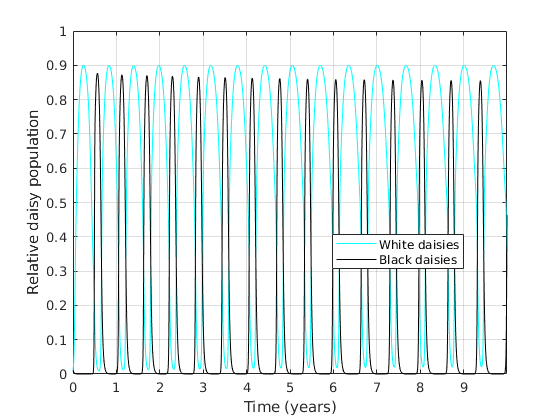

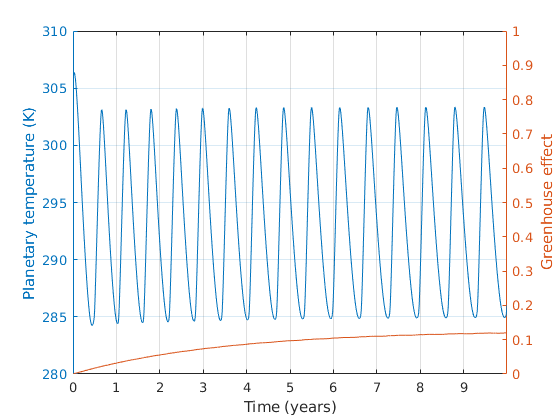

[alphaW,alphaB,T_global,E] = ...
    daisyWorld(t,Irradiance,L,alphaW0,alphaB0,gamma);


clf;close all;
plotResults_daisyWorld(alphaW,alphaB,T_global,E,t)

## Constant Irradiance and death rate = 0.25

-  The planetary temperature becomes almost constant once the black daisy population get close to zero. 

- The daisy death rate has a significant influence on the "eauilibrium" between the two flowers population. If you take gamma = 0.2, for example, the population of black daisies still survives after 10 years.

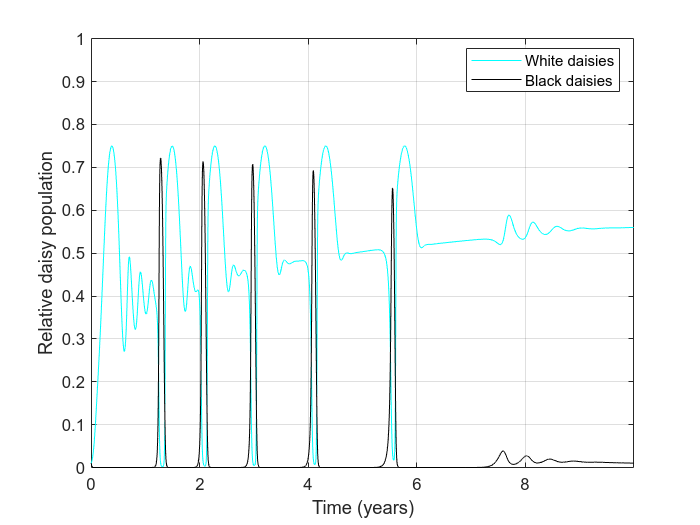

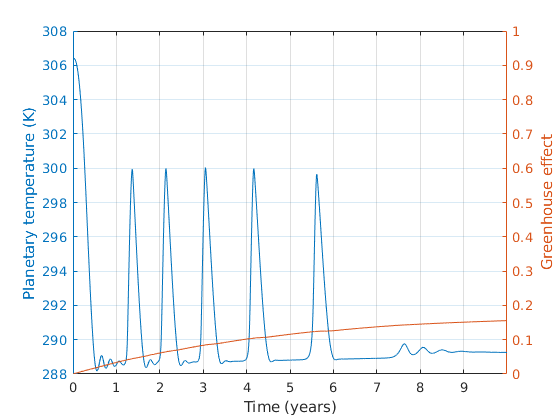

gamma = 0.25 ;
[alphaW,alphaB,T_global,E] =...
    daisyWorld(t,Irradiance,L,alphaW0,alphaB0,gamma);

clf;close all;
plotResults_daisyWorld(alphaW,alphaB,T_global,E,t)

## Variability of Irradiance (seasonal) - no trend

-    The perturbation of the system by a time-varying irradiance has only a minor effect on the equilibrium between black and white daisies population.   We could say that the system is "resilient" to such perturbations.

-    The stationary state is reached after ca. 5000 days, as shown by the constant greenhouse effect values

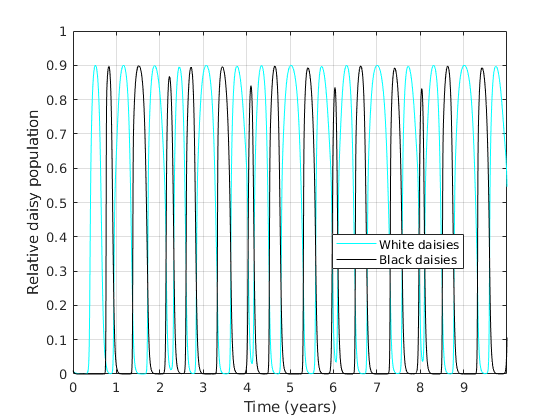

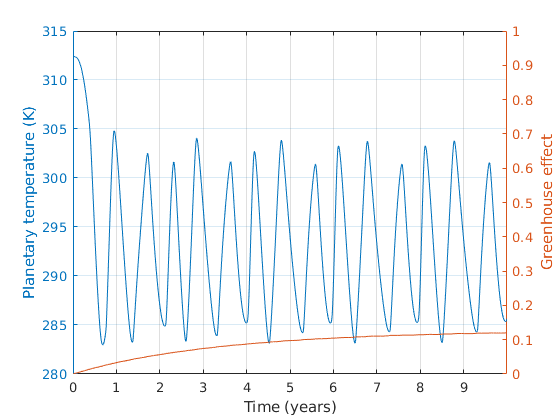

gamma = 0.10 ; %
N = round(10*365*fs) ; % we want 5 years of simulation
t = [0:N-1].*dt ; % time vector
L = 1*ones(1,N) ; % Luminosity (L = 1 for same luminosity as for the sun)
Irradiance = 900.*(1+0.2*cos(2*pi*t/365)) ; % W/m^2  --> Irradiance from the sun at the surface of the planet with a period of 24 h

[alphaW,alphaB,T_global,E] =...
    daisyWorld(t,Irradiance,L,alphaW0,alphaB0,gamma);

clf;close all;
plotResults_daisyWorld(alphaW,alphaB,T_global,E,t)

## Linear increase of the luminosity

   1) After 15 years, both daisy population got extinct. It was not visible after 10years of simulation but it was predictable. 

   2) Once the white daisies die, the albedo of the planet decreases, which leads to a sudden increase in its temperature.

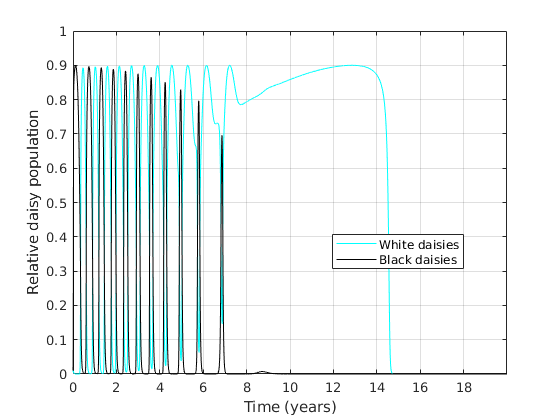

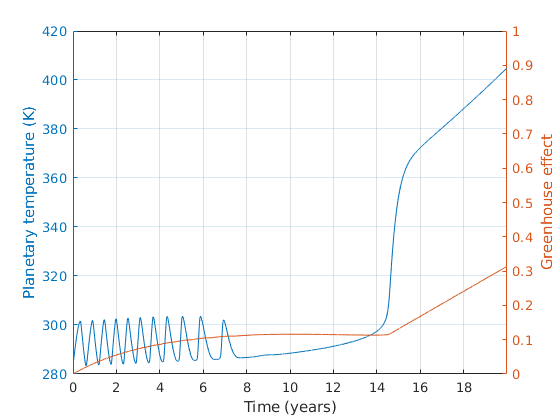

N = round(20*365*fs) ; % we want 1 years of simulation
t = [0:N-1].*dt ; % time vector
Irradiance = 1000*ones(1,N) ; % W/m^2  --> Irradiance from the sun at the surface of the planet
L = 1.9e-4*t+0.75; % Luminosity (L = 1 for same luminosity as for the sun)

[alphaW,alphaB,T_global,E] =...
    daisyWorld(t,Irradiance,L,alphaW0,alphaB0,gamma);

clf;close all;
plotResults_daisyWorld(alphaW,alphaB,T_global,E,t)

## No absorption coefficient by the planet

Not enough greenhouse gas can be absorbed, so the episodes of high temperature are getting longer and longer until the black daisies all die.  This leads to a slow but steady increase of the global temperature from year 10 to 15. Once the white daisies population got extinct, the temperature sharply increases due to the albedo of the ground, which is lower than that of white daisies

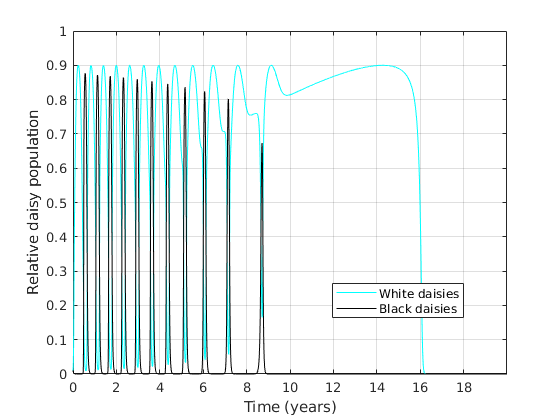

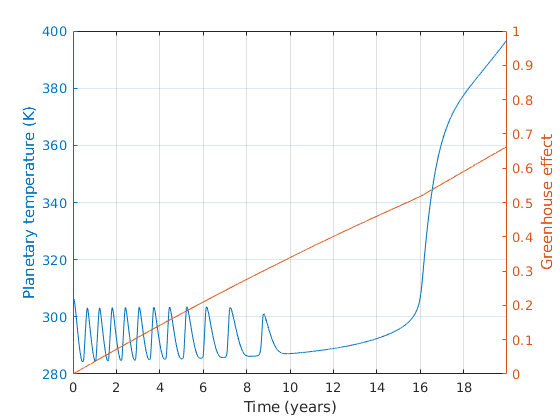

dt = 1 ; % time step is one day
fs = 1/dt ; % sampling frequency
N = round(20*365*fs) ; % we want 1 years of simulation
t = (0:N-1)*dt ; % time vector
Irradiance = 1000*ones(1,N) ; % W/m^2  --> Irradiance from the sun at the surface of the planet
L = 1*ones(1,N) ; % Luminosity (L = 1 for same luminosity as for the sun)
a = 1e-4;
b = 5e-5;
[alphaW,alphaB,T_global,E] =...
    daisyWorld(t,Irradiance,L,alphaW0,alphaB0,gamma,'a',a,'b',b);

clf;close all;
plotResults_daisyWorld(alphaW,alphaB,T_global,E,t)